%calculating the mean first passage time analytically/numerically 
%to investigate effect of branch migration domain on DNA/DNA toehold
%exchange kinetics including spontaneous incumbent dissociation

g = 3 %define invader toehold length

g = 3

g2 = 1 %define incumbent toehold length

g2 = 1


R = 1.987/1000 % universal gas constant in kcal/K/mol 

R = 0.0020

temp = 298.15 %temperature in K

temp = 298.1500

%free energy parameters
dGassoc = 2.6*R*temp

dGassoc = 1.5403

dGbp = -2.52*R*temp

dGbp = -1.4929

dGp = 3.6*R*temp

dGp = 2.1327

dGbm = 7.4*R*temp 

dGbm = 4.3839

%absolute rate constant 
k_bp = 5.4*10^7

k_bp = 54000000

k_eff = zeros(1,30)

k_eff =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time = zeros(1, 30)

first_pass_time =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


prob_unbound = zeros(1, 30)

prob_unbound =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0



%loop through branch migration domain lengths
for b = 10:40
    bg2 = b + g2 %define branch migration domain + incumbent toehold length 

    %define forward and reverse transition rates
    k_AA = 0;
    k_AB1 = k_bp * exp(-dGassoc/(R*temp)) * (5*10^-8)
    k_B1A = k_bp * exp(dGbp/(R*temp))
    k_BC1ij = k_bp;
    k_BC1ji = k_bp * exp(dGbp/(R*temp));
    k_C1f = k_bp * exp(-(dGbm + dGp)/(R*temp))
    k_Cf = k_bp * exp(-dGbm/(R*temp))
    k_Cr = k_bp * exp(-dGbm/(R*temp));
    k_DC = k_bp * exp(-(dGbm + dGp)/(R*temp))
    k_DEij = k_bp * exp(dGbp/(R*temp));
    k_DEji = k_bp;
    k_EF = k_bp * exp(dGbp/(R*temp))
    k_FE = 0
    k_FF = 1    
    
    %create arrays of forward and reverse transition rates
    Kf = [k_FF, k_EF, repmat(k_DEij, [1, g2-1]), repmat(k_Cf, [1, b-1]), k_C1f, repmat(k_BC1ij, [1, g-2]), k_BC1ij, k_AB1]
    Kb = [k_FE, repmat(k_DEji, [1, g2-1]), k_DC, repmat(k_Cr, [1, b-1]), k_BC1ji, repmat(k_BC1ji, [1, g-2]), k_B1A, k_AA]
    
    %define spontaneous incumbent dissociation rates
    Koff = [repmat(0, [1, g2+1])]; 
    for n = g2 + 1:bg2-1
        Koff = horzcat(Koff, [k_bp*exp(-(n*(-dGbp))/(R*temp))]);
    end
    Koff = horzcat(Koff, [repmat(0, [1, g+1])])
    
    Pn_jN_1 = zeros(1,numel(Kf))
    jn_jN_1 = zeros(1,numel(Kf))
    Pn_jN_1 (1) = 0;
    jn_jN_1 (1) = 1;
        
    %calculate flux between each state
    for Pn = 2:numel(Kf)
        Pn_jN_1(Pn)  = 1/Kf(Pn) * jn_jN_1 (Pn-1) + (Kb(Pn-1)/Kf(Pn))*Pn_jN_1(Pn-1);
        jn_jN_1(Pn) = jn_jN_1(Pn-1) + Koff(Pn) * Pn_jN_1(Pn);
    end
        
    first_pass_time (b-9) = (1/jn_jN_1(end-1))*sum(Pn_jN_1) %calculate first passage time
    k_eff (b-9) = 1/(first_pass_time (b-9)*(5*10^-8)); %calculate effective rate constant
    prob_unbound(b-9) = Pn_jN_1(end)/sum(Pn_jN_1) %calculate probability of being in unbound state
end

bg2 = 11

k_AB1 = 0.2005

k_B1A = 4.3448e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_DC = 901.8918

k_EF = 4.3448e+06

k_FE = 0

k_FF = 1

Kf = 	1.0e+07 *

    0.0000    0.4345    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    0.0000


Kb = 	1.0e+06 *

         0    0.0009    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    4.3448    4.3448    4.3448         0


Koff = 	1.0e+05 *

         0         0    3.4958    0.2813    0.0226    0.0018    0.0001    0.0000    0.0000    0.0000    0.0000         0         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time = 	1.0e+03 *

    1.3079         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound =     1.0000         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


bg2 = 12

k_AB1 = 0.2005

k_B1A = 4.3448e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_DC = 901.8918

k_EF = 4.3448e+06

k_FE = 0

k_FF = 1

Kf = 	1.0e+07 *

    0.0000    0.4345    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    0.0000


Kb = 	1.0e+06 *

         0    0.0009    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    4.3448    4.3448    4.3448         0


Koff = 	1.0e+05 *

         0         0    3.4958    0.2813    0.0226    0.0018    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time = 	1.0e+03 *

    1.3079    1.4634         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound =     1.0000    1.0000         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


bg2 = 13

k_AB1 = 0.2005

k_B1A = 4.3448e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_DC = 901.8918

k_EF = 4.3448e+06

k_FE = 0

k_FF = 1

Kf = 	1.0e+07 *

    0.0000    0.4345    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    0.0000


Kb = 	1.0e+06 *

         0    0.0009    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    4.3448    4.3448    4.3448         0


Koff = 	1.0e+05 *

         0         0    3.4958    0.2813    0.0226    0.0018    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time = 	1.0e+03 *

    1.3079    1.4634    1.6189         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound =     1.0000    1.0000    1.0000         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


bg2 = 14

k_AB1 = 0.2005

k_B1A = 4.3448e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_DC = 901.8918

k_EF = 4.3448e+06

k_FE = 0

k_FF = 1

Kf = 	1.0e+07 *

    0.0000    0.4345    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    0.0000


Kb = 	1.0e+06 *

         0    0.0009    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    4.3448    4.3448    4.3448         0


Koff = 	1.0e+05 *

         0         0    3.4958    0.2813    0.0226    0.0018    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time = 	1.0e+03 *

    1.3079    1.4634    1.6189    1.7744         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound =     1.0000    1.0000    1.0000    1.0000         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


bg2 = 15

k_AB1 = 0.2005

k_B1A = 4.3448e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_DC = 901.8918

k_EF = 4.3448e+06

k_FE = 0

k_FF = 1

Kf = 	1.0e+07 *

    0.0000    0.4345    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    0.0000


Kb = 	1.0e+06 *

         0    0.0009    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    4.3448    4.3448    4.3448         0


Koff = 	1.0e+05 *

         0         0    3.4958    0.2813    0.0226    0.0018    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time = 	1.0e+03 *

    1.3079    1.4634    1.6189    1.7744    1.9300         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound =     1.0000    1.0000    1.0000    1.0000    1.0000         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


bg2 = 16

k_AB1 = 0.2005

k_B1A = 4.3448e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_DC = 901.8918

k_EF = 4.3448e+06

k_FE = 0

k_FF = 1

Kf = 	1.0e+07 *

    0.0000    0.4345    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    0.0000


Kb = 	1.0e+06 *

         0    0.0009    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    4.3448    4.3448    4.3448         0


Koff = 	1.0e+05 *

         0         0    3.4958    0.2813    0.0226    0.0018    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time = 	1.0e+03 *

    1.3079    1.4634    1.6189    1.7744    1.9300    2.0855         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


bg2 = 17

k_AB1 = 0.2005

k_B1A = 4.3448e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_DC = 901.8918

k_EF = 4.3448e+06

k_FE = 0

k_FF = 1

Kf = 	1.0e+07 *

    0.0000    0.4345    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    0.0000


Kb = 	1.0e+06 *

         0    0.0009    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    4.3448    4.3448    4.3448         0


Koff = 	1.0e+05 *

         0         0    3.4958    0.2813    0.0226    0.0018    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time = 	1.0e+03 *

    1.3079    1.4634    1.6189    1.7744    1.9300    2.0855    2.2410         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


bg2 = 18

k_AB1 = 0.2005

k_B1A = 4.3448e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_DC = 901.8918

k_EF = 4.3448e+06

k_FE = 0

k_FF = 1

Kf =     0.0000    0.4345    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    0.0000


Kb =          0    0.0009    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    4.3448    4.3448    4.3448         0


Koff =          0         0    3.4958    0.2813    0.0226    0.0018    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time =     1.3079    1.4634    1.6189    1.7744    1.9300    2.0855    2.2410    2.3965         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


bg2 = 19

k_AB1 = 0.2005

k_B1A = 4.3448e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_DC = 901.8918

k_EF = 4.3448e+06

k_FE = 0

k_FF = 1

Kf =     0.0000    0.4345    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    0.0000


Kb =          0    0.0009    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    4.3448    4.3448    4.3448         0


Koff =          0         0    3.4958    0.2813    0.0226    0.0018    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time =     1.3079    1.4634    1.6189    1.7744    1.9300    2.0855    2.2410    2.3965    2.5520         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


bg2 = 20

k_AB1 = 0.2005

k_B1A = 4.3448e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_DC = 901.8918

k_EF = 4.3448e+06

k_FE = 0

k_FF = 1

Kf =     0.0000    0.4345    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    0.0000


Kb =          0    0.0009    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    4.3448    4.3448    4.3448         0


Koff =          0         0    3.4958    0.2813    0.0226    0.0018    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time =     1.3079    1.4634    1.6189    1.7744    1.9300    2.0855    2.2410    2.3965    2.5520    2.7075         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


bg2 = 21

k_AB1 = 0.2005

k_B1A = 4.3448e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_DC = 901.8918

k_EF = 4.3448e+06

k_FE = 0

k_FF = 1

Kf =     0.0000    0.4345    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    0.0000


Kb =          0    0.0009    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    4.3448    4.3448    4.3448         0


Koff =          0         0    3.4958    0.2813    0.0226    0.0018    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time =     1.3079    1.4634    1.6189    1.7744    1.9300    2.0855    2.2410    2.3965    2.5520    2.7075    2.8631         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


bg2 = 22

k_AB1 = 0.2005

k_B1A = 4.3448e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_DC = 901.8918

k_EF = 4.3448e+06

k_FE = 0

k_FF = 1

Kf =     0.0000    0.4345    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    0.0000


Kb =          0    0.0009    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    4.3448    4.3448    4.3448         0


Koff =          0         0    3.4958    0.2813    0.0226    0.0018    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time =     1.3079    1.4634    1.6189    1.7744    1.9300    2.0855    2.2410    2.3965    2.5520    2.7075    2.8631    3.0186         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


bg2 = 23

k_AB1 = 0.2005

k_B1A = 4.3448e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_DC = 901.8918

k_EF = 4.3448e+06

k_FE = 0

k_FF = 1

Kf =     0.0000    0.4345    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    0.0000


Kb =          0    0.0009    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    4.3448    4.3448    4.3448         0


Koff =          0         0    3.4958    0.2813    0.0226    0.0018    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time =     1.3079    1.4634    1.6189    1.7744    1.9300    2.0855    2.2410    2.3965    2.5520    2.7075    2.8631    3.0186    3.1741         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


bg2 = 24

k_AB1 = 0.2005

k_B1A = 4.3448e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_DC = 901.8918

k_EF = 4.3448e+06

k_FE = 0

k_FF = 1

Kf =     0.0000    0.4345    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    0.0000


Kb =          0    0.0009    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    4.3448    4.3448    4.3448         0


Koff =          0         0    3.4958    0.2813    0.0226    0.0018    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time =     1.3079    1.4634    1.6189    1.7744    1.9300    2.0855    2.2410    2.3965    2.5520    2.7075    2.8631    3.0186    3.1741    3.3296         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


bg2 = 25

k_AB1 = 0.2005

k_B1A = 4.3448e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_DC = 901.8918

k_EF = 4.3448e+06

k_FE = 0

k_FF = 1

Kf =     0.0000    0.4345    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    0.0000


Kb =          0    0.0009    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    4.3448    4.3448    4.3448         0


Koff =          0         0    3.4958    0.2813    0.0226    0.0018    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time =     1.3079    1.4634    1.6189    1.7744    1.9300    2.0855    2.2410    2.3965    2.5520    2.7075    2.8631    3.0186    3.1741    3.3296    3.4851         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


bg2 = 26

k_AB1 = 0.2005

k_B1A = 4.3448e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_DC = 901.8918

k_EF = 4.3448e+06

k_FE = 0

k_FF = 1

Kf =     0.0000    0.4345    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    0.0000


Kb =          0    0.0009    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    4.3448    4.3448    4.3448         0


Koff =          0         0    3.4958    0.2813    0.0226    0.0018    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time =     1.3079    1.4634    1.6189    1.7744    1.9300    2.0855    2.2410    2.3965    2.5520    2.7075    2.8631    3.0186    3.1741    3.3296    3.4851    3.6407         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000         0         0         0         0         0         0         0         0         0         0         0         0         0         0


bg2 = 27

k_AB1 = 0.2005

k_B1A = 4.3448e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_DC = 901.8918

k_EF = 4.3448e+06

k_FE = 0

k_FF = 1

Kf =     0.0000    0.4345    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000


Kb =          0    0.0009    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    4.3448    4.3448    4.3448


Koff =          0         0    3.4958    0.2813    0.0226    0.0018    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time =     1.3079    1.4634    1.6189    1.7744    1.9300    2.0855    2.2410    2.3965    2.5520    2.7075    2.8631    3.0186    3.1741    3.3296    3.4851    3.6407    3.7962         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000         0         0         0         0         0         0         0         0         0         0         0         0         0


bg2 = 28

k_AB1 = 0.2005

k_B1A = 4.3448e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_DC = 901.8918

k_EF = 4.3448e+06

k_FE = 0

k_FF = 1

Kf =     0.0000    0.4345    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000


Kb =          0    0.0009    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    4.3448    4.3448


Koff =          0         0    3.4958    0.2813    0.0226    0.0018    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time =     1.3079    1.4634    1.6189    1.7744    1.9300    2.0855    2.2410    2.3965    2.5520    2.7075    2.8631    3.0186    3.1741    3.3296    3.4851    3.6407    3.7962    3.9517         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000         0         0         0         0         0         0         0         0         0         0         0         0


bg2 = 29

k_AB1 = 0.2005

k_B1A = 4.3448e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_DC = 901.8918

k_EF = 4.3448e+06

k_FE = 0

k_FF = 1

Kf =     0.0000    4.3448    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0009


Kb =          0    0.0009    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    4.3448


Koff =          0         0    3.4958    0.2813    0.0226    0.0018    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time =     1.3079    1.4634    1.6189    1.7744    1.9300    2.0855    2.2410    2.3965    2.5520    2.7075    2.8631    3.0186    3.1741    3.3296    3.4851    3.6407    3.7962    3.9517    4.1072         0         0         0         0         0         0         0         0         0         0         0


prob_unbound =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000         0         0         0         0         0         0         0         0         0         0         0


bg2 = 30

k_AB1 = 0.2005

k_B1A = 4.3448e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_DC = 901.8918

k_EF = 4.3448e+06

k_FE = 0

k_FF = 1

Kf =     0.0000    4.3448    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330


Kb =          0    0.0902    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008


Koff =          0         0    3.4958    0.2813    0.0226    0.0018    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time =     1.3079    1.4634    1.6189    1.7744    1.9300    2.0855    2.2410    2.3965    2.5520    2.7075    2.8631    3.0186    3.1741    3.3296    3.4851    3.6407    3.7962    3.9517    4.1072    4.2627         0         0         0         0         0         0         0         0         0         0


prob_unbound =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000         0         0         0         0         0         0         0         0         0         0


bg2 = 31

k_AB1 = 0.2005

k_B1A = 4.3448e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_DC = 901.8918

k_EF = 4.3448e+06

k_FE = 0

k_FF = 1

Kf =     0.0000    4.3448    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330


Kb =          0    0.0902    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008


Koff =          0         0    3.4958    0.2813    0.0226    0.0018    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time =     1.3079    1.4634    1.6189    1.7744    1.9300    2.0855    2.2410    2.3965    2.5520    2.7075    2.8631    3.0186    3.1741    3.3296    3.4851    3.6407    3.7962    3.9517    4.1072    4.2627    4.4182         0         0         0         0         0         0         0         0         0


prob_unbound =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000         0         0         0         0         0         0         0         0         0


bg2 = 32

k_AB1 = 0.2005

k_B1A = 4.3448e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_DC = 901.8918

k_EF = 4.3448e+06

k_FE = 0

k_FF = 1

Kf =     0.0000    4.3448    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330


Kb =          0    0.0902    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008


Koff =          0         0    3.4958    0.2813    0.0226    0.0018    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time =     1.3079    1.4634    1.6189    1.7744    1.9300    2.0855    2.2410    2.3965    2.5520    2.7075    2.8631    3.0186    3.1741    3.3296    3.4851    3.6407    3.7962    3.9517    4.1072    4.2627    4.4182    4.5738         0         0         0         0         0         0         0         0


prob_unbound =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000         0         0         0         0         0         0         0         0


bg2 = 33

k_AB1 = 0.2005

k_B1A = 4.3448e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_DC = 901.8918

k_EF = 4.3448e+06

k_FE = 0

k_FF = 1

Kf =     0.0000    4.3448    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330


Kb =          0    0.0902    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008


Koff =          0         0    3.4958    0.2813    0.0226    0.0018    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time =     1.3079    1.4634    1.6189    1.7744    1.9300    2.0855    2.2410    2.3965    2.5520    2.7075    2.8631    3.0186    3.1741    3.3296    3.4851    3.6407    3.7962    3.9517    4.1072    4.2627    4.4182    4.5738    4.7293         0         0         0         0         0         0         0


prob_unbound =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000         0         0         0         0         0         0         0


bg2 = 34

k_AB1 = 0.2005

k_B1A = 4.3448e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_DC = 901.8918

k_EF = 4.3448e+06

k_FE = 0

k_FF = 1

Kf =     0.0000    4.3448    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330


Kb =          0    0.0902    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008


Koff =          0         0    3.4958    0.2813    0.0226    0.0018    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time =     1.3079    1.4634    1.6189    1.7744    1.9300    2.0855    2.2410    2.3965    2.5520    2.7075    2.8631    3.0186    3.1741    3.3296    3.4851    3.6407    3.7962    3.9517    4.1072    4.2627    4.4182    4.5738    4.7293    4.8848         0         0         0         0         0         0


prob_unbound =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000         0         0         0         0         0         0


bg2 = 35

k_AB1 = 0.2005

k_B1A = 4.3448e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_DC = 901.8918

k_EF = 4.3448e+06

k_FE = 0

k_FF = 1

Kf =     0.0000    4.3448    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330


Kb =          0    0.0902    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008


Koff =          0         0    3.4958    0.2813    0.0226    0.0018    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time =     1.3079    1.4634    1.6189    1.7744    1.9300    2.0855    2.2410    2.3965    2.5520    2.7075    2.8631    3.0186    3.1741    3.3296    3.4851    3.6407    3.7962    3.9517    4.1072    4.2627    4.4182    4.5738    4.7293    4.8848    5.0403         0         0         0         0         0


prob_unbound =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000         0         0         0         0         0


bg2 = 36

k_AB1 = 0.2005

k_B1A = 4.3448e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_DC = 901.8918

k_EF = 4.3448e+06

k_FE = 0

k_FF = 1

Kf =     0.0000    4.3448    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330


Kb =          0    0.0902    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008


Koff =          0         0    3.4958    0.2813    0.0226    0.0018    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time =     1.3079    1.4634    1.6189    1.7744    1.9300    2.0855    2.2410    2.3965    2.5520    2.7075    2.8631    3.0186    3.1741    3.3296    3.4851    3.6407    3.7962    3.9517    4.1072    4.2627    4.4182    4.5738    4.7293    4.8848    5.0403    5.1958         0         0         0         0


prob_unbound =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000         0         0         0         0


bg2 = 37

k_AB1 = 0.2005

k_B1A = 4.3448e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_DC = 901.8918

k_EF = 4.3448e+06

k_FE = 0

k_FF = 1

Kf =     0.0000    4.3448    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330


Kb =          0    0.0902    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008


Koff =          0         0    3.4958    0.2813    0.0226    0.0018    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time =     1.3079    1.4634    1.6189    1.7744    1.9300    2.0855    2.2410    2.3965    2.5520    2.7075    2.8631    3.0186    3.1741    3.3296    3.4851    3.6407    3.7962    3.9517    4.1072    4.2627    4.4182    4.5738    4.7293    4.8848    5.0403    5.1958    5.3514         0         0         0


prob_unbound =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000         0         0         0


bg2 = 38

k_AB1 = 0.2005

k_B1A = 4.3448e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_DC = 901.8918

k_EF = 4.3448e+06

k_FE = 0

k_FF = 1

Kf =     0.0000    4.3448    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330


Kb =          0    0.0902    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008


Koff =          0         0    3.4958    0.2813    0.0226    0.0018    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time =     1.3079    1.4634    1.6189    1.7744    1.9300    2.0855    2.2410    2.3965    2.5520    2.7075    2.8631    3.0186    3.1741    3.3296    3.4851    3.6407    3.7962    3.9517    4.1072    4.2627    4.4182    4.5738    4.7293    4.8848    5.0403    5.1958    5.3514    5.5069         0         0


prob_unbound =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000         0         0


bg2 = 39

k_AB1 = 0.2005

k_B1A = 4.3448e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_DC = 901.8918

k_EF = 4.3448e+06

k_FE = 0

k_FF = 1

Kf =     0.0000    4.3448    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330


Kb =          0    0.0902    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008


Koff =          0         0    3.4958    0.2813    0.0226    0.0018    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time =     1.3079    1.4634    1.6189    1.7744    1.9300    2.0855    2.2410    2.3965    2.5520    2.7075    2.8631    3.0186    3.1741    3.3296    3.4851    3.6407    3.7962    3.9517    4.1072    4.2627    4.4182    4.5738    4.7293    4.8848    5.0403    5.1958    5.3514    5.5069    5.6624         0


prob_unbound =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000         0


bg2 = 40

k_AB1 = 0.2005

k_B1A = 4.3448e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_DC = 901.8918

k_EF = 4.3448e+06

k_FE = 0

k_FF = 1

Kf =     0.0000    4.3448    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330


Kb =          0    0.0902    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008


Koff =          0         0    3.4958    0.2813    0.0226    0.0018    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time =     1.3079    1.4634    1.6189    1.7744    1.9300    2.0855    2.2410    2.3965    2.5520    2.7075    2.8631    3.0186    3.1741    3.3296    3.4851    3.6407    3.7962    3.9517    4.1072    4.2627    4.4182    4.5738    4.7293    4.8848    5.0403    5.1958    5.3514    5.5069    5.6624    5.8179


prob_unbound =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000


bg2 = 41

k_AB1 = 0.2005

k_B1A = 4.3448e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_DC = 901.8918

k_EF = 4.3448e+06

k_FE = 0

k_FF = 1

Kf =     0.0000    4.3448    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330


Kb =          0    0.0902    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008


Koff =          0         0    3.4958    0.2813    0.0226    0.0018    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time =     1.3079    1.4634    1.6189    1.7744    1.9300    2.0855    2.2410    2.3965    2.5520    2.7075    2.8631    3.0186    3.1741    3.3296    3.4851    3.6407    3.7962    3.9517    4.1072    4.2627    4.4182    4.5738    4.7293    4.8848    5.0403    5.1958    5.3514    5.5069    5.6624    5.8179


prob_unbound =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000


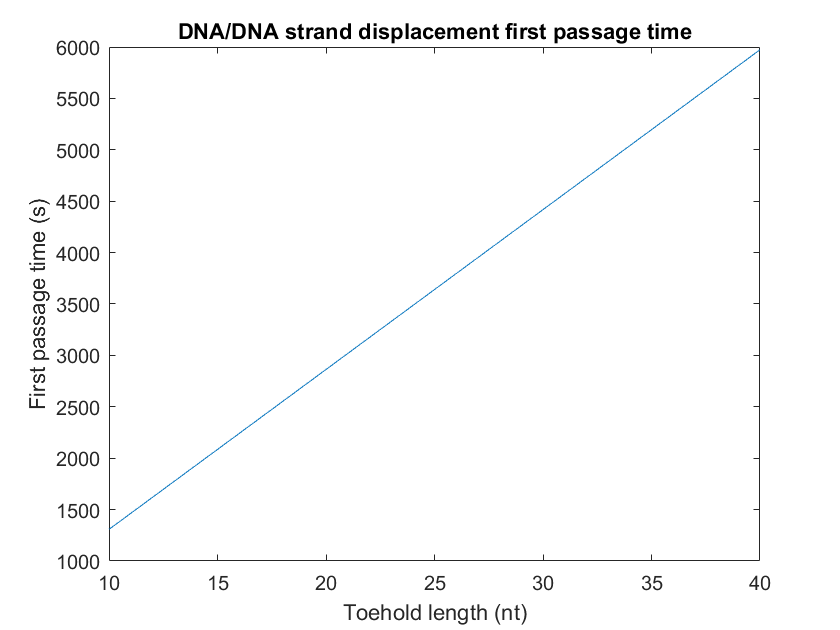

plot(10:40, first_pass_time)
ylabel('First passage time (s)')
xlabel('Toehold length (nt)')
title('DNA/DNA strand displacement first passage time')

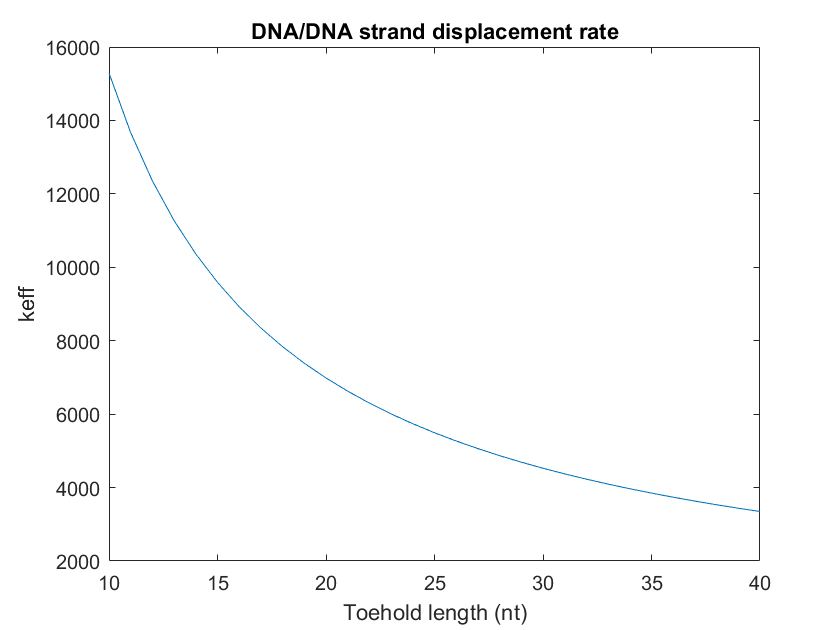


plot(10:40, k_eff)
xlabel('Toehold length (nt)')
ylabel('keff')
title('DNA/DNA strand displacement rate')

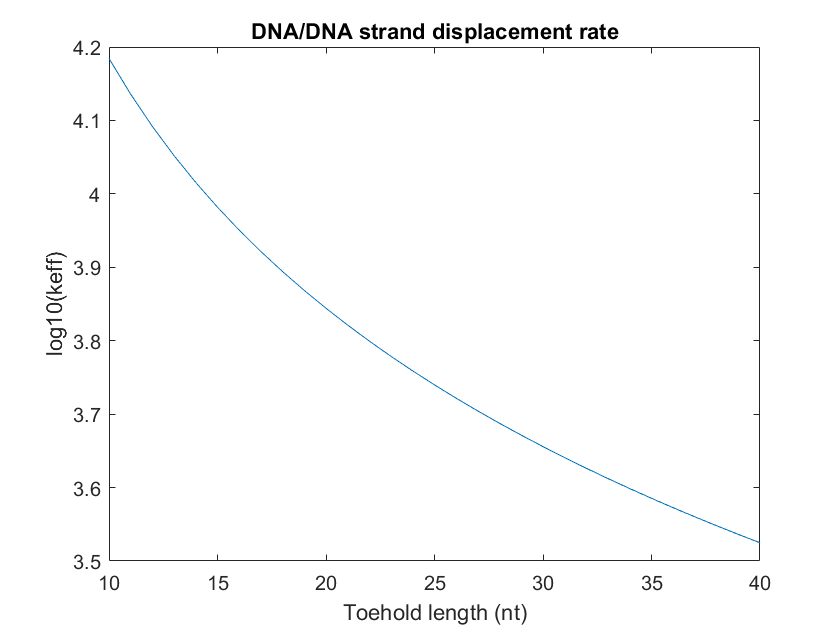


plot(10:40, log10(k_eff))
xlabel('Toehold length (nt)')
ylabel('log10(keff)')
title('DNA/DNA strand displacement rate')  